%% fMRI Activation Map
%
% Find the pixels that are dominated by the same period as the reference
% signal and display those on an image of the brain
%
% x is a 122 by 64 by 64 "matrix" containing length 122 time signals
% for a 64 by 64 pixel horizontal slice through the brain.

## Set up workspace

clear
close all

load fmri.mat

## Find magnitude of periodicity at each pixel

% MATLAB DFT index corresponding to periodic task
ref_indx = 7;

for i=1:64
    for j=1:64 % pixel index i,j
        
        s = x(:,i,j);  % pixel i,j time series
        
        S = abs(fft(s)); % DFT coeff magnitude of pixel i,j time series
        
        Val(i,j) = S(ref_indx); % DFT coeff mag at reference frequency
        
    end
end

## Create thresholded activation map

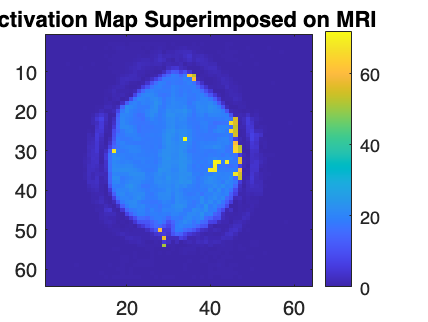

A = zeros(64,64); % initialize activation map

thresh = 650;

[I] = find(Val>thresh); % I : indices of pixels in Val that exceed thresh
A(I) = 1;  % set "active" pixels to one

% Get anatomy by using pixel values at first time sample
im = reshape(x(1,:,:),64,64); % 64 by 64 matrix im

figure
% Combine a low level MRI (im/50) with high level activation map (A*50) to
% superimpose the activation map on the anatomy in a visually pleasing
% manner.  Other scalings are also acceptable.

imagesc(im/50+A*50) % use imagesc() for MATLAB 2019b or newer
% Note: Use %image(im/50+A*50) for MATLAB 2019a or older
colorbar
title('Activation Map Superimposed on MRI')

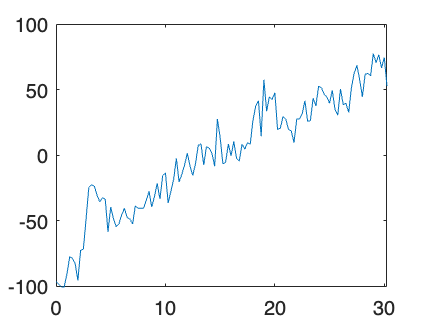

% Write Code Below
x_z = x(:,12,36)-mean(x(:,12,36));
N = length(s);
fs = 4;
t = (0:N-1)/fs;
plot(t, x_z)


x_z = x(:,12,36)-mean(x(:,12,36));
N = length(s);
fs = 4;
t = (0:N-1)/fs;
plot(t, x_z)

## (Optional) Devise and Test a better Strategy